# Train Network for Sequence Classification

Train a deep learning LSTM network for sequence-to-label classification.

Load the Japanese Vowels data set as described in [1] and [2]. `XTrain` is a cell array containing 270 sequences of varying length with 12 features corresponding to LPC cepstrum coefficients. `Y` is a categorical vector of labels 1,2,...,9. The entries in `XTrain` are matrices with 12 rows (one row for each feature) and a varying number of columns (one column for each time step).

[X,Y] = japaneseVowelsTrainData;

% split dataset to (train, val)
% percentages of (train, val, test) for splitEachLabel
len_X = length(X);
len_train = double(0.8 * len_X);
len_val = len_X - len_train;

XTrain = X(1 : len_train);
YTrain = Y(1 : len_train);

XVal = X(1 : len_train);
YVal = Y(1 : len_train);



 Visualize the first time series in a plot. Each line corresponds to a feature.

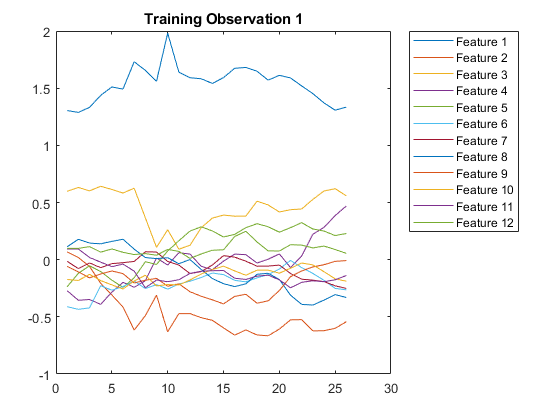

figure
plot(XTrain{2}')
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

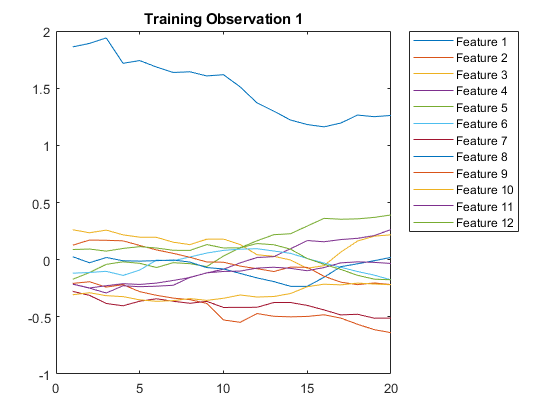

Define the LSTM network architecture. Specify the input size as 12 (the number of features of the input data). Specify an LSTM layer to have 100 hidden units and to output the last element of the sequence. Finally, specify nine classes by including a fully connected layer of size 9, followed by a softmax layer and a classification layer.

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize, 'Name', 'input')
    lstmLayer(numHiddenUnits,'OutputMode','last', 'Name', 'lstm')
    fullyConnectedLayer(numClasses, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')]

layers =   5×1 Layer array with layers:

     1   'input'            Sequence Input          Sequence input with 12 dimensions
     2   'lstm'             LSTM                    LSTM with 100 hidden units
     3   'fc'               Fully Connected         9 fully connected layer
     4   'softmax'          Softmax                 softmax
     5   'classification'   Classification Output   crossentropyex

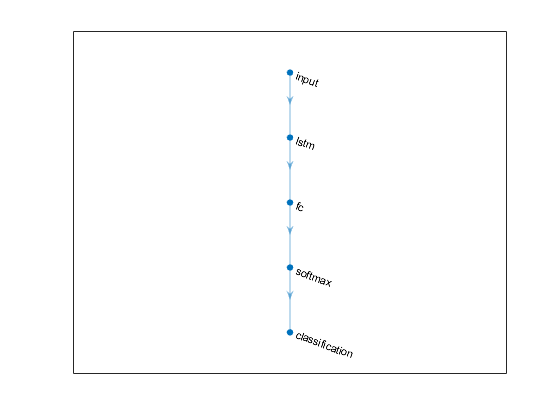


lgraph = layerGraph(layers);
figure;
plot(lgraph);

Specify the training options. Specify the solver as `'adam'` and `'GradientThreshold'` as 1. Set the mini-batch size to 27 and set the maximum number of epochs to 70.

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

% miniBatchSize = 32;
% MaxEpochs = 70;
% InitialLearnRate = 0.001;
% L2Regularization =0.01;
% validationFrequency = floor(numel(trueLabelsTrain)/miniBatchSize);
% 
% options = trainingOptions( ...
%     'adam', ...
%     'Plots', 'training-progress', ...
%     'Verbose', true, ...
%     'MaxEpochs', MaxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'Shuffle', 'every-epoch', ...
%     'ValidationData', {XTest, YTest}, ...
%     'ValidationFrequency', validationFrequency, ...
%     'InitialLearnRate', InitialLearnRate, ...
%     'LearnRateSchedule', 'piecewise', ...
%     'LearnRateDropPeriod', 1, ...
%     'LearnRateDropFactor', 0.1, ...
%     'L2Regularization', L2Regularization, ...
%     'SequencePaddingDirection', 'left' ...
%     );

maxEpochs = 70;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ValidationData', {XVal, YVal} ...
    );

Train the LSTM network with the specified training options.

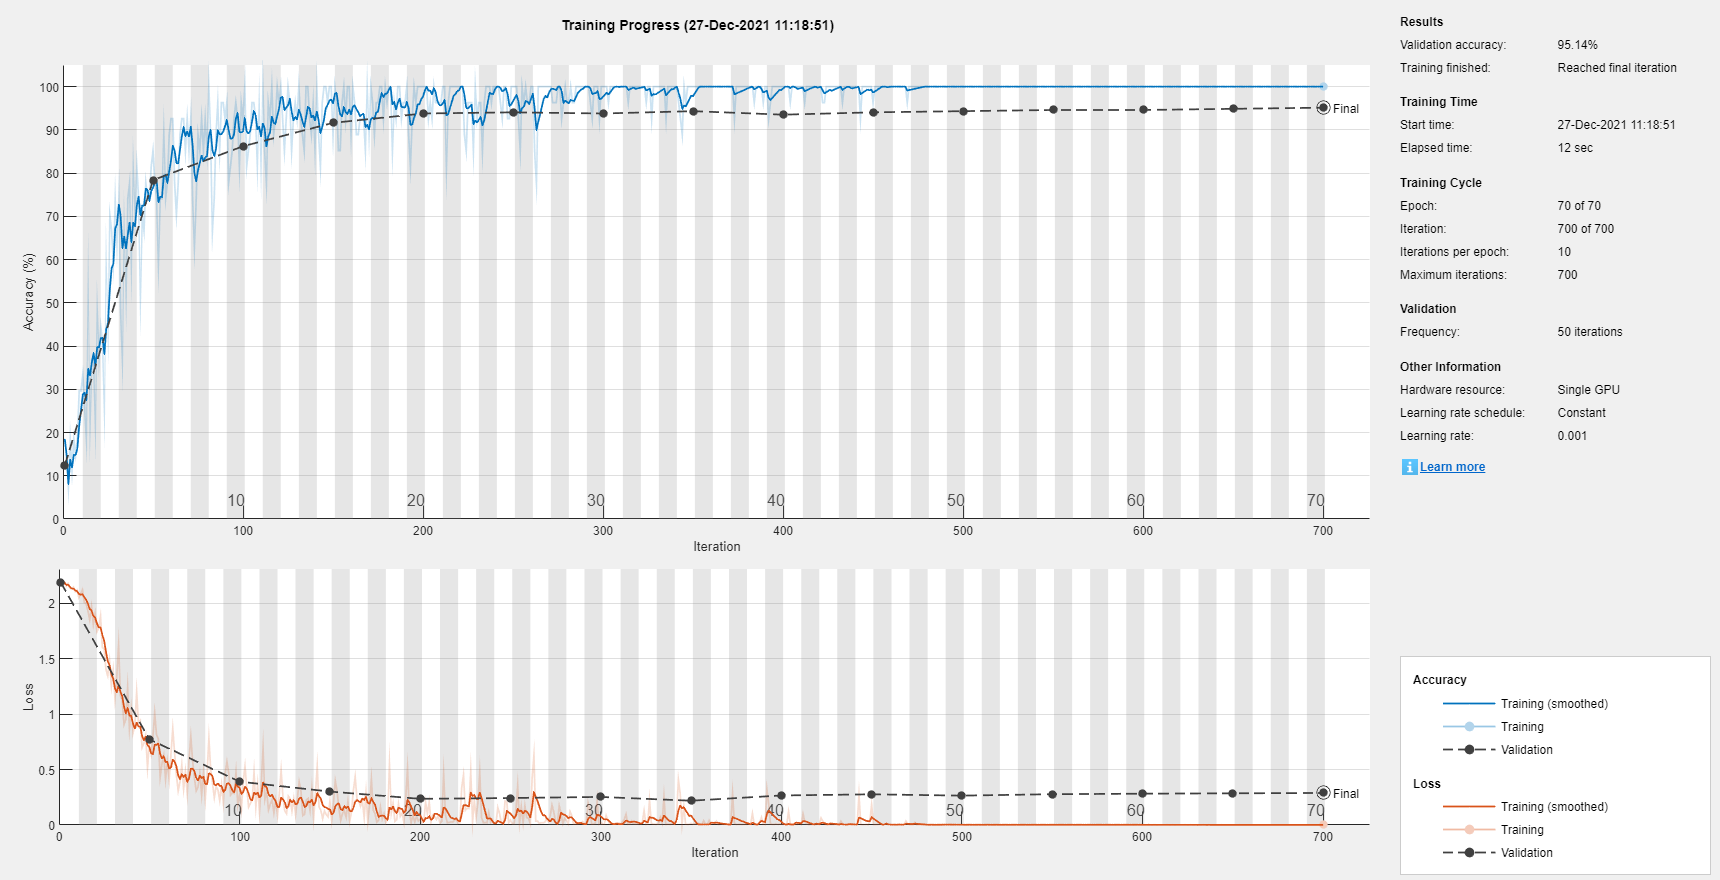

net = trainNetwork(XTrain,YTrain,layers,options);

Load the test set and classify the sequences into speakers.

[XTest,YTest] = japaneseVowelsTestData;

Classify the test data. Specify the same mini-batch size used for training.

YPred = classify(net,XTest,'MiniBatchSize',miniBatchSize);

Calculate the classification accuracy of the predictions.

acc = sum(YPred == YTest)./numel(YTest);
disp(acc);

*Copyright 2017 The MathWorks, Inc.*

% disp(net.Layers);
% analyzeNetwork(net);